# Top view plot

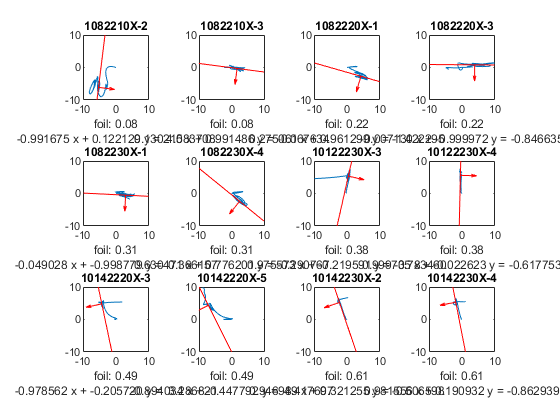

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure(1)
clf;
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
        % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        ax(i) = subplot(3,4,i);
        plot(x,y);
        hold on;
        plot(xline,yline,'-r');
        hold on;
        quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        title(FileName{i});
        xlim([-10, 10]);
        ylim([-10, 10]);;
        xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d)})
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        save(path,'traj3D','Plane');
    end
end
savefig('10_oil_TopViewTraj.fig')

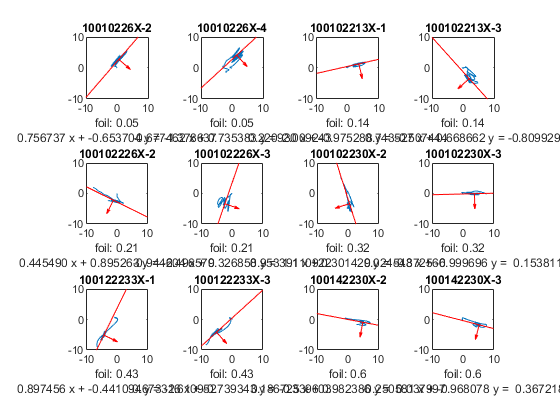

figure(2)
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
       % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        subplot(3,4,i-12);
        plot(x,y);
        hold on;
        plot(xline,yline,'-r');
        hold on;
        quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        title(FileName{i});
        xlim([-10, 10]);
        ylim([-10, 10]);
        xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d)})
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        save(path,'traj3D','Plane');
    end
end
savefig('100_oil_TopViewTraj.fig')

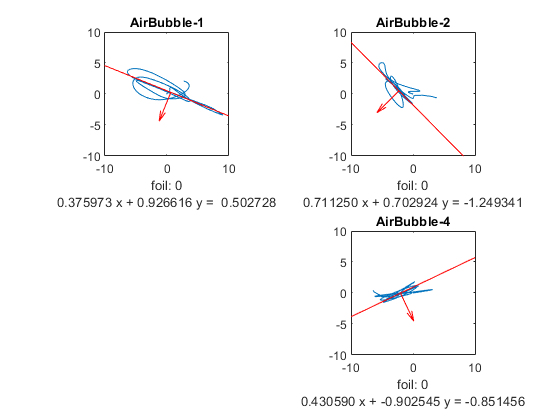

figure(3)
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
         % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        subplot(2,2,i-24);
        plot(x,y);
        hold on;
        plot(xline,yline,'-r');
        hold on;
        quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        title(FileName{i});
        xlim([-10, 10]);
        ylim([-10, 10]);
        xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d)})
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        save(path,'traj3D','Plane');
    end
end
savefig('Air_TopViewTraj.fig')

## Sideview projection plot

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure();
clf;
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = Plane(3);
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
        yV = [0, -1];
        theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
        if -1/AntiSlope/LengthUnit < 0
            theta = -theta
        end
        ax(i) = subplot(3,4,i);
        plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        xlim([-10, 10]);
        ylim([-10, 10]);
        zlim([0, 200]);
        view(theta, 0);
        title(FileName{i});
    end
end

theta = -7.4817

theta = -15.9677

theta = -0.4085

theta = -2.8103

theta = -39.0853

theta = -78.1278

theta = -63.3952

theta = -71.2611

theta = -78.9923

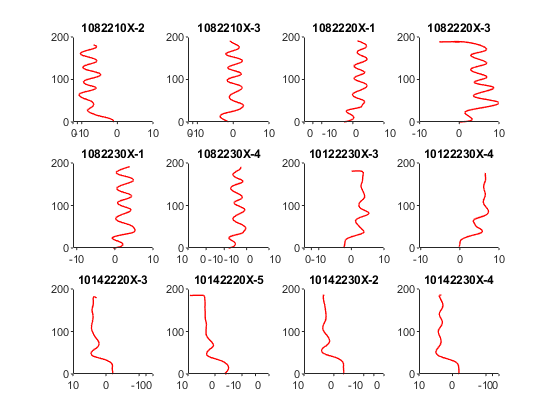

savefig('BestPlaneView10Oil.fig')

figure();
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = Plane(3);
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
        yV = [0, -1];
        theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
        if -1/AntiSlope/LengthUnit < 0
            theta = -theta
        end
        ax(i) = subplot(3,4,i - 12);
        plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        xlim([-10, 10]);
        ylim([-10, 10]);
        zlim([0, 200]);
        view(theta, 0);
        title(FileName{i});
    end
end

theta = -48.0346

theta = -26.4553

theta = -72.4549

theta = -10.7620

theta = -14.5122

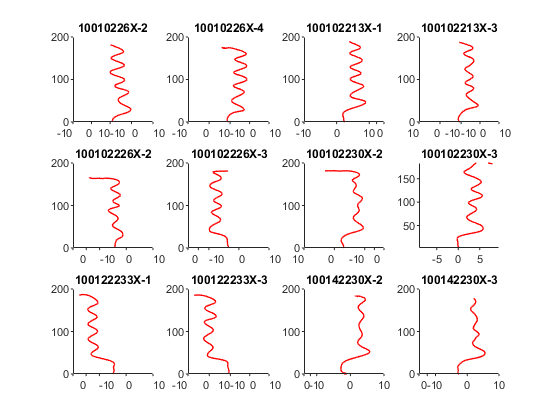

savefig('BestPlaneView100Oil.fig')

figure();
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = Plane(3);
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
        yV = [0, -1];
        theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
        if -1/AntiSlope/LengthUnit < 0
            theta = -theta
        end
        ax(i) = subplot(2,2,i - 24);
        plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        xlim([-10, 10]);
        ylim([-10, 10]);
        zlim([0, 200]);
        view(theta, 0);
        title(FileName{i});
    end
end

theta = -22.0848

theta = -45.3373

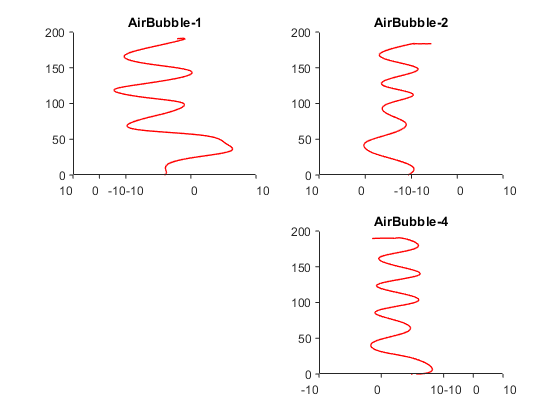

savefig('BestPlaneViewAir.fig')

## Velocity analysis

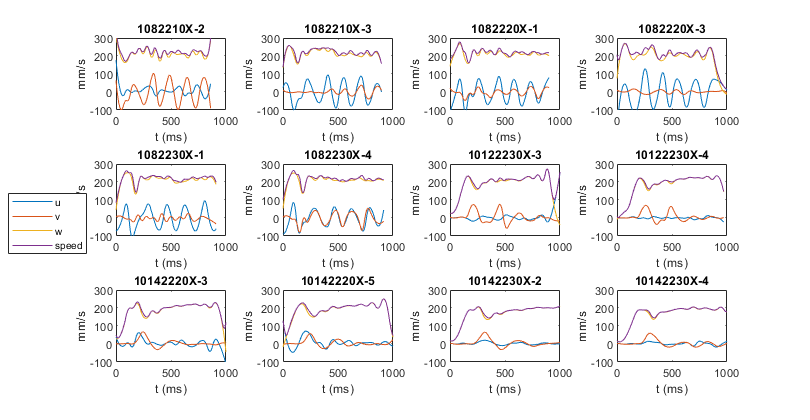

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure();
clf;
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        subplot(3,4,i);
        plot(xplot,u);
        hold on;
        plot(xplot,v);
        hold on;
        plot(xplot,w);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel('t (ms)');
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('u','v','w','speed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('Velocity10oil.fig')
saveas(gcf,'Velocity10oil.png')

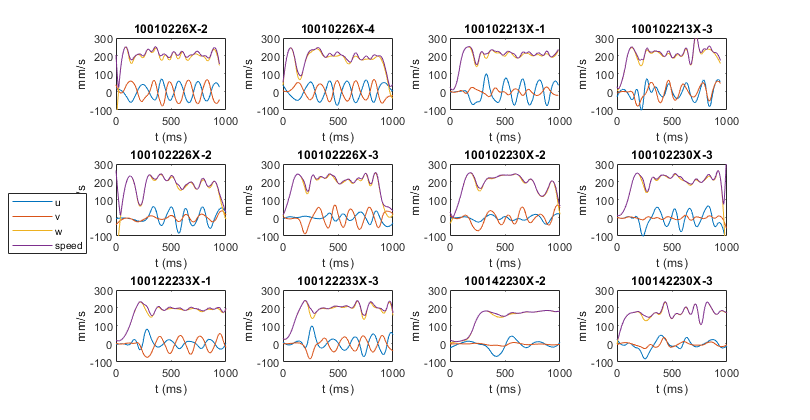

figure();
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        subplot(3,4,i-12);
        plot(xplot,u);
        hold on;
        plot(xplot,v);
        hold on;
        plot(xplot,w);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel('t (ms)');
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('u','v','w','speed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('Velocity100oil.fig')
saveas(gcf,'Velocity100oil.png')

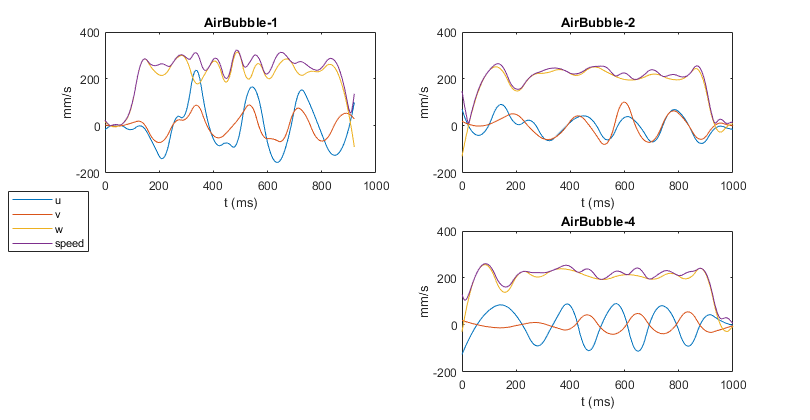

figure();
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        subplot(2,2,i-24);
        plot(xplot,u);
        hold on;
        plot(xplot,v);
        hold on;
        plot(xplot,w);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel('t (ms)');
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('u','v','w','speed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('VelocityAir.fig')
saveas(gcf,'VelocityAir.png')